# Exercise 5 - Gregor Alič

clear all;
close all;
T = 0.01;

## System

### Static curve

N = 300

N = 300

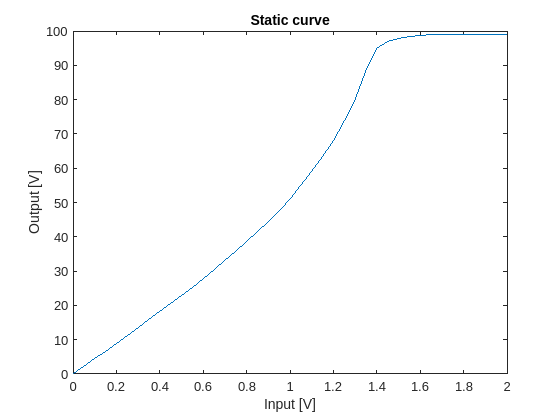


dV = 0.05;
c = zeros(2 / dV + 1, 1);

for V = 0:dV:2
    
    u = ones(N, 1) * V;

    y = simulate_helicrane(u, [0, 0]);
    y_m = mean(y(100:end));

    c(round(V/dV) + 1) = y_m;
end

figure;
plot(0:dV:2, c);
title("Static curve");
xlabel("Input [V]");
ylabel("Output [V]");

## APRBS

[u_train, t_train] = APRBS(3000, 2.5, T, 0.20, 100); % 2.0V to keep response bounded

[u_test, t_test] = APRBS(3000, 2.0, T, 0.20, 100); % 2.0V to keep response bounded

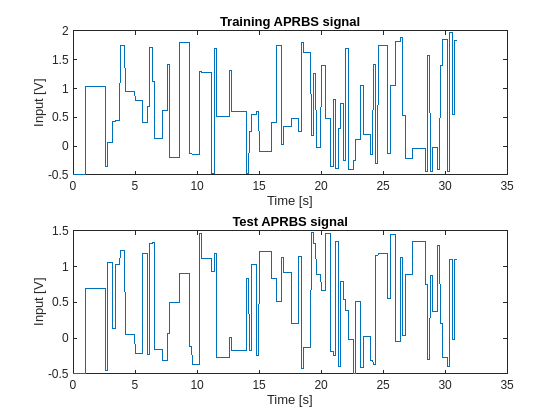

u_train = u_train - 0.5;
u_test = u_test - 0.5;

figure
subplot(2, 1, 1);
plot(t_train, u_train);
title("Training APRBS signal")
xlabel("Time [s]");
ylabel("Input [V]");

subplot(2, 1, 2);
plot(t_test, u_test);
title("Test APRBS signal");
xlabel("Time [s]");
ylabel("Input [V]");

## System response

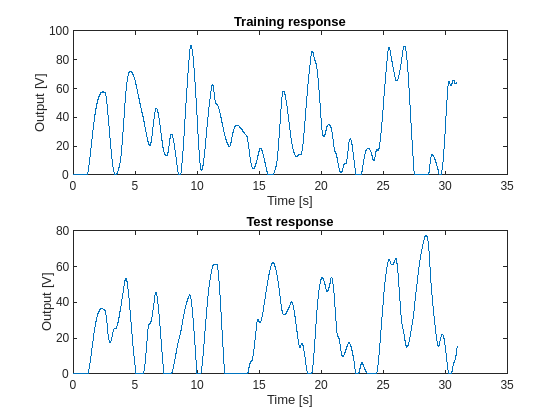

y_train = simulate_helicrane(u_train, [0 0]);
y_test = simulate_helicrane(u_test, [0 0]);

figure
subplot(2, 1, 1);
plot(t_train, y_train);
title("Training response")
xlabel("Time [s]");
ylabel("Output [V]");

subplot(2, 1, 2);
plot(t_test, y_test);
title("Test response")
xlabel("Time [s]");
ylabel("Output [V]");

## Neural network

### Generate datasets

X_train = [u_train(2:end-1), u_train(1:end-2), -y_train(2:end-1), -y_train(1:end-2)];
Y_train = y_train(3:end);

perm = randperm(size(X_train, 1));
X_train_shuffled = X_train(perm, :);
Y_train_shuffled = Y_train(perm, :);

X_test = [u_test(2:end-1), u_test(1:end-2), -y_test(2:end-1), -y_test(1:end-2)];
Y_test = y_test(3:end);

### Train the neural network

net = feedforwardnet([12, 5]);
net.layers{1}.transferFcn = 'tansig';
net.layers{2}.transferFcn = 'tansig';
net.layers{3}.transferFcn = 'purelin';
net.trainParam.showWindow = false;
net.trainParam.goal = 2e-6;

[net, ~] = train(net, X_train_shuffled', Y_train_shuffled');

### Results

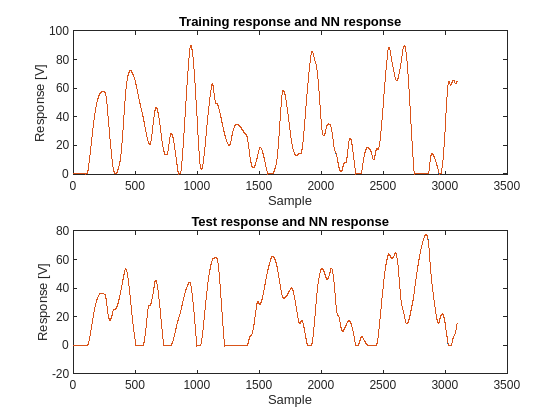

figure;

subplot(2, 1, 1);
plot(Y_train);
title("Training response and NN response")
hold on;
plot(net(X_train'));
xlabel("Sample")
ylabel("Response [V]")

subplot(2, 1, 2);
plot(Y_test);
title("Test response and NN response")
hold on;
plot(net(X_test'));
xlabel("Sample")
ylabel("Response [V]")

### Fully simulated

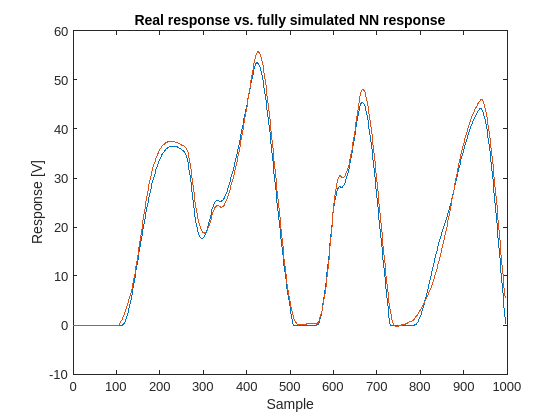

X_sim = X_test(1, :);
Y_sim = [];

for i = 3:998
    y = net(X_sim');
    Y_sim = [Y_sim, y];
    X_sim = [u_test(i), u_test(i-1), -y, X_sim(3)]; 
end

figure
plot(Y_test(2:998));
title("Real response vs. fully simulated NN response")
hold on;
plot(Y_sim);
xlabel("Sample")
ylabel("Response [V]")

## Takagi Sugeno model

R = 15; % number of rules
n = size(X_train', 1); % dimensions of data
N = size(X_train', 2); % number of data points
[C, O , W, b, e]  = TS_train(rand(R, 2), [20, 20] + rand(R, 2), 4*rand(R, n) - 2, 4*rand(R, 1) - 2, X_train_shuffled', Y_train_shuffled', 0.000002, 400);

Epoch 1: Error: 66.592176
Epoch 101: Error: 0.385032
Epoch 201: Error: 0.274032
Epoch 301: Error: 0.205508
Final error: 0.158799


### Results

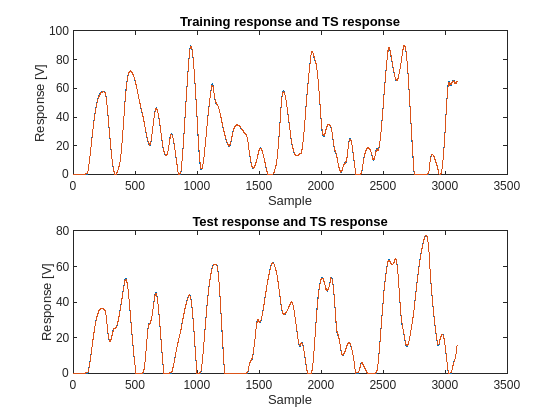

figure;

subplot(2, 1, 1);
plot(Y_train);
title("Training response and TS response")
hold on;
plot(TS_eval(C, O, W, b, X_train'));
xlabel("Sample")
ylabel("Response [V]")

subplot(2, 1, 2);
plot(Y_test);
title("Test response and TS response")
hold on;
plot(TS_eval(C, O, W, b, X_test'));
xlabel("Sample")
ylabel("Response [V]")

### Fully simulated

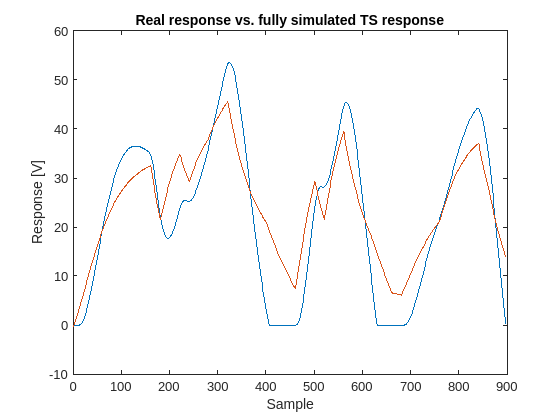

X_sim = X_test(100, :);
Y_sim = [];

for i = 102:998
    y = TS_eval(C, O, W, b, X_sim');
    Y_sim = [Y_sim, y];
    X_sim = [u_test(i), u_test(i-1), -y, X_sim(3)]; 
end

figure
plot(Y_test(102:998));
title("Real response vs. fully simulated TS response")
hold on;
plot(Y_sim);
xlabel("Sample")
ylabel("Response [V]")

Save results

save("ts.mat", "C", "O", "W", "b");